addpath('Classes')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',false);
sympref('TypesetOutput',true);

clear BP_Kinetics

# **Kinetics and Deriving Nonlinear Equations of Motion Class Developement Script**

This script aids in the developement and documentation of the BP_Kinetics class. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics

end 

%Derive the Nonlinear Equations of motion in one go (may break this up into separate functions
%later, not sure yet)
[Omega2b, Hb2s, Hb2ds, SumMBall, Hp1s, Hp1ds, armp1s, rb1s, ap1s,...
                ab1s, Hb1ds, SumMPlate, CoeffMat, ExtTerms, NL_EOMs] = BP_Kinetics.Derive_NL_EOMs;

$$CoeffMat = \left[\begin{array}{cccc} 0 & -m_{b}\,r_{b}\,x\,\sin\left(\gamma \right) & \frac{7\,m_{b}\,r_{b}}{5} & -m_{b}\,r_{b}\,z_{b}-\frac{2\,m_{b}\,{r_{b}}^{2}}{5}\\ -\frac{7\,m_{b}\,r_{b}}{5} & -\frac{2\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}-m_{b}\,r_{b}\,z_{b}\,\cos\left(\gamma \right)-m_{b}\,r_{b}\,y\,\sin\left(\gamma \right) & 0 & 0\\ 0 & m_{b}\,x\,y\,{\cos\left(\gamma \right)}^{3}-m_{b}\,x\,z_{b}\,{\sin\left(\gamma \right)}^{3}+m_{b}\,x\,y\,\cos\left(\gamma \right)\,{\sin\left(\gamma \right)}^{2}-m_{b}\,x\,z_{b}\,{\cos\left(\gamma \right)}^{2}\,\sin\left(\gamma \right) & \frac{2\,m_{b}\,r_{b}}{5}+m_{b}\,z_{b}\,{\cos\left(\gamma \right)}^{2}+m_{b}\,z_{b}\,{\sin\left(\gamma \right)}^{2} & -I_{p}^{\mathrm{xx}}-\frac{2\,m_{b}\,{r_{b}}^{2}}{5}-m_{b}\,y^{2}\,{\cos\left(\gamma \right)}^{2}-m_{b}\,{z_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}-m_{p}\,{z_{p}}^{2}\,{\cos\left(\gamma \right)}^{2}-m_{b}\,y^{2}\,{\sin\left(\gamma \right)}^{2}-m_{b}\,{z_{b}}^{2}\,{\sin\left(\gamma \right)}^{2}-m_{p}\,{z_{p}}^{2}\,{\sin\left(\gamma \right)}^{2}\\ -\frac{2\,m_{b}\,r_{b}\,\cos\left(\gamma \right)}{5}-m_{b}\,z_{b}\,\cos\left(\gamma \right)-m_{b}\,y\,\sin\left(\gamma \right) & -I_{p}^{\mathrm{xx}}\,{\cos\left(\gamma \right)}^{2}-I_{p}^{\mathrm{zz}}\,{\sin\left(\gamma \right)}^{2}-\frac{2\,m_{b}\,{r_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}}{5}-m_{b}\,x^{2}\,{\cos\left(\gamma \right)}^{2}-m_{b}\,{z_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}-m_{p}\,{z_{p}}^{2}\,{\cos\left(\gamma \right)}^{2}-\frac{2\,m_{b}\,{r_{b}}^{2}\,{\sin\left(\gamma \right)}^{2}}{5}-m_{b}\,x^{2}\,{\sin\left(\gamma \right)}^{2}-m_{b}\,y^{2}\,{\sin\left(\gamma \right)}^{2}-2\,m_{b}\,y\,z_{b}\,\cos\left(\gamma \right)\,\sin\left(\gamma \right) & m_{b}\,x\,\sin\left(\gamma \right) & m_{b}\,x\,y\,\cos\left(\gamma \right)-m_{b}\,x\,z_{b}\,\sin\left(\gamma \right) \end{array}\right]$$


%Input estimated numerical parameters of the system and simplify the system with a few assumptions
[Num_Params, Sym_Params, Assumption_Params, Assumptions, NL_NumEOMs] = BP_Kinetics.Num_Params_n_Assumptions;

## Methodology

Now that the kinematics for the sytem have been formulated, we can move on to the Newton-Euler kinetic analysis. The sum of moment equations for the ball and for the combined ball and plate system will be used to determine the equations of motion. This analysis will further couple the states of our system together and it will bring in the externally applied torques. The flow of work to arrive at the equations of motion will be as such:

- For both FBD = KD system, formulate the angular momentum vector/s$H$in terms of the pertinent kinematic variables.

- Rotate that $H$ vector/s into the global reference frame and differentiate it/them to get the time rates of change of angular momentum. 

- Write out the sum of moments equation for both FBD = KD systems, placing the force moments on the left hand side of the equation and the kinetic diagram moments on the right hand side. Do this generally, in terms of moment arms and cross products. 

- Carry out the cross products to get the moment equations relating the system's dynamic variables to each other and to the externally applied torques. 

- Choose an appropriate state vector for the system.

- Combine the moment equations of the two FBD = KD systems and isolate the highest order derivatives of the state variables. These will be the equations of motion for the sytem. 

- Substitute in numerical estimates of the system parameters and make some final simplifying assumptions.

## Kinetics of the Ball Alone

We will sum moments in frame S2 about ball's contact point to eliminate the unkown forces. The vectors in the kinetic diagram of figure 3 must be formulated in terms of the kinematic variables found earlier in this analysis. The normal force and friction forces will be eliminated from the equation by strategically summing moments about the contact point of the ball, the point where those forces act. 

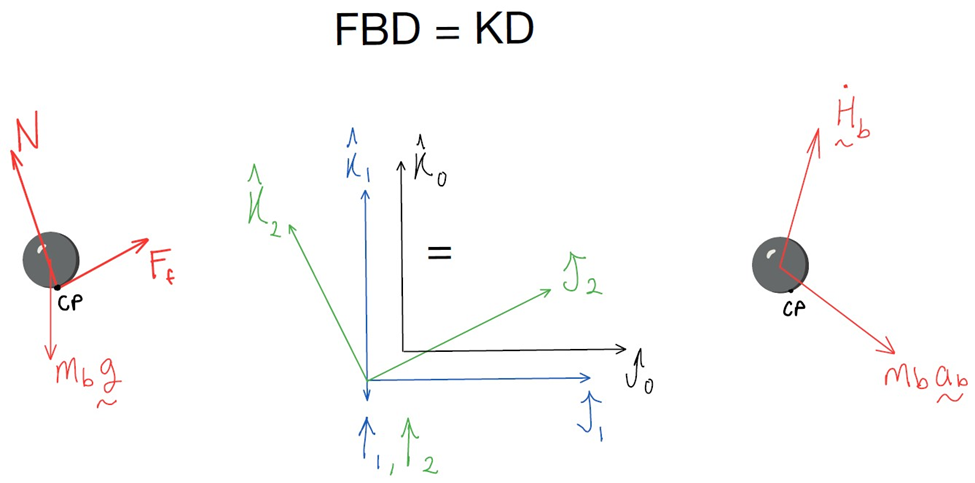

Figure 3: Free body diagram and kinetic diagram for the ball alone. $N$ is the normal force and $F_f$ is the friction force. 

### Absolute Angular Momentum$H^{(2)}_b$of the Ball About its C.O.M 

This quantity is taken about center of mass of the ball and expressed in the S2 Basis. The ball's global angular velocity is the sum of the plate's angular velocity and the ball's angular velocity within the plate's frame S2. This results in an angular velocity equation of


$$H_b^{(2)} ~=~ I_b^{(2)}*(\hat{\Omega}^{(2)} + \Psi^{(2)})$$


where $I_b^{(2)}$ is the inertia tensor of the ball.


$$I_b^{(2)} = \left\lbrack \begin{array}{ccc}
I_b  & 0 & 0\\
0 & I_b  & 0\\
0 & 0 & I_b 
\end{array}\right\rbrack$$


Thus, the ball's angular momentum is:

subs(Hb2s, VDefs.symFunVec, VDefs.symVarVec) %Display the angular momentum vector in an easier to read format

$$ans = \left[\begin{array}{c} -\frac{2\,m_{b}\,r_{b}\,\dot{y}}{5}+\frac{2\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}}{5}\\ \frac{2\,m_{b}\,r_{b}\,\dot{x}}{5}+\frac{2\,\dot{\beta }\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}\\ \frac{2\,m_{b}\,\psi_{z}\,{r_{b}}^{2}}{5}-\frac{2\,\dot{\beta }\,m_{b}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5} \end{array}\right]$$


$$H_b^{(2)} ~=~

\left\lbrack \begin{array}{c}
I_b \,\gamma^˙ -\frac{I_b \,\dot{y} }{r_b }\\
I_b \,\beta^˙ \,\mathrm{cos}\left(\gamma \right)+\frac{I_b \,\dot{x} }{r_b }\\
I_b \,\psi_z -I_b \,\beta^˙ \,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack

~=~

\left\lbrack \begin{array}{c}
-\frac{2\,m_b \,r_b \,\dot{y} }{5}+\frac{2\,\dot{\gamma} \,m_b \,{r_b }^2 }{5}\\
\frac{2\,m_b \,r_b \,\dot{x} }{5}+\frac{2\,\dot{\beta} \,m_b \,{r_b }^2 \,\cos \left(\gamma \right)}{5}\\
\frac{2\,m_b \,\psi_z \,{r_b }^2 }{5}-\frac{2\,\dot{\beta} \,m_b \,{r_b }^2 \,\sin \left(\gamma \right)}{5}
\end{array}\right\rbrack$$


### Take the Time Derivative of Absolute Angular Momentum,$\dot{H}^{(2)}_b$, With Respect to the Inertial Reference Frame

We must transform $H^{(2)}_b$ into the S0 global basis, take a time derivative, then transform back to the S2 basis. Taking the derivative with respect to an inertial reference frame ensures compliance with Newton's laws. The result of this procedure is:

Hb2ds

$$Hb2ds = \left[\begin{array}{c} \frac{2\,\ddot{\gamma }\,m_{b}\,{r_{b}}^{2}}{5}-\frac{2\,m_{b}\,r_{b}\,\ddot{y}}{5}+\frac{2\,\dot{\beta }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{x}\,\sin\left(\gamma \right)}{5}\\ \frac{2\,m_{b}\,r_{b}\,\ddot{x}}{5}-\frac{2\,\dot{\gamma }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}}{5}+\frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}-\frac{2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{y}\,\sin\left(\gamma \right)}{5}\\ \frac{2\,m_{b}\,{\dot{\psi }}_{z}\,{r_{b}}^{2}}{5}+\frac{2\,\dot{\gamma }\,m_{b}\,r_{b}\,\dot{x}}{5}-\frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5}-\frac{2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{y}\,\cos\left(\gamma \right)}{5} \end{array}\right]$$


$$\dot{H}_b^{(2)} 

~=~

\left\lbrack \begin{array}{c}
I_b \,\gamma^¨ -\frac{I_b \,\ddot{y} }{r_b }+I_b \,\beta^˙ \,\psi_z \,\mathrm{cos}\left(\gamma \right)+\frac{I_b \,\beta^˙ \,\dot{x} \,\mathrm{sin}\left(\gamma \right)}{r_b }\\
I_b \,\beta^¨ \,\mathrm{cos}\left(\gamma \right)-I_b \,\gamma^˙ \,\psi_z +\frac{I_b \,\ddot{x} }{r_b }-I_b \,\beta^˙ \,\gamma^˙ \,\mathrm{sin}\left(\gamma \right)+\frac{I_b \,\beta^˙ \,\dot{y} \,\mathrm{sin}\left(\gamma \right)}{r_b }\\
I_b \,{\psi^˙ }_z -I_b \,\beta^¨ \,\mathrm{sin}\left(\gamma \right)-I_b \,\beta^˙ \,\gamma^˙ \,\mathrm{cos}\left(\gamma \right)+\frac{I_b \,\gamma^˙ \,\dot{x} }{r_b }+\frac{I_b \,\beta^˙ \,\dot{y} \,\mathrm{cos}\left(\gamma \right)}{r_b }
\end{array}\right\rbrack

~=~

\left\lbrack \begin{array}{c}
\frac{2\,\ddot{\gamma} \,m_b \,{r_b }^2 }{5}-\frac{2\,m_b \,r_b \,\ddot{y} }{5}+\frac{2\,\dot{\beta} \,m_b \,\psi_z \,{r_b }^2 \,\cos \left(\gamma \right)}{5}+\frac{2\,\dot{\beta} \,m_b \,r_b \,\dot{x} \,\sin \left(\gamma \right)}{5}\\
\frac{2\,m_b \,r_b \,\ddot{x} }{5}-\frac{2\,\dot{\gamma} \,m_b \,\psi_z \,{r_b }^2 }{5}+\frac{2\,\ddot{\beta} \,m_b \,{r_b }^2 \,\cos \left(\gamma \right)}{5}-\frac{2\,\dot{\beta} \,\dot{\gamma} \,m_b \,{r_b }^2 \,\sin \left(\gamma \right)}{5}+\frac{2\,\dot{\beta} \,m_b \,r_b \,\dot{y} \,\sin \left(\gamma \right)}{5}\\
\frac{2\,m_b \,{\dot{\psi} }_z \,{r_b }^2 }{5}+\frac{2\,\dot{\gamma} \,m_b \,r_b \,\dot{x} }{5}-\frac{2\,\ddot{\beta} \,m_b \,{r_b }^2 \,\sin \left(\gamma \right)}{5}-\frac{2\,\dot{\beta} \,\dot{\gamma} \,m_b \,{r_b }^2 \,\cos \left(\gamma \right)}{5}+\frac{2\,\dot{\beta} \,m_b \,r_b \,\dot{y} \,\cos \left(\gamma \right)}{5}
\end{array}\right\rbrack$$


### Sum of Moments About Contact Point of the Ball

The moment arm to the ball's center of mass here is the radius of the ball $r_b$ in the plate's z-direction as before


$$arm_b^{(2)} = \left\lbrack \begin{array}{c}
0\\
0\\
r_b 
\end{array}\right\rbrack$$


The sum of moments about point CP on the free body diagram is equal to the sum of the moments about point CP on the kinetic diagram. 


$$

\begin{array}{rl}

\sum{M_{cp~FBD} &=~~ \sum{M_{cp~KD}\\[6pt]

arm^{(2)}_b \times R^{02}W^{(0)}_b 
&=~~  arm^{(2)}_b \times m_b a^{(2)}_b + \dot{H}^{(2)}_b

\end{array}$$


Resulting in a set of moment equations

SumMBall

$$SumMBall = \left[\begin{array}{c} g\,m_{b}\,r_{b}\,\cos\left(\beta \right)\,\sin\left(\gamma \right)=\frac{2\,\ddot{\gamma }\,m_{b}\,{r_{b}}^{2}}{5}-\frac{7\,m_{b}\,r_{b}\,\ddot{y}}{5}+\ddot{\gamma }\,m_{b}\,r_{b}\,z_{b}+{\dot{\beta }}^{2}\,m_{b}\,r_{b}\,y+{\dot{\gamma }}^{2}\,m_{b}\,r_{b}\,y+\frac{2\,\dot{\beta }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}-{\dot{\beta }}^{2}\,m_{b}\,r_{b}\,y\,{\cos\left(\gamma \right)}^{2}+\ddot{\beta }\,m_{b}\,r_{b}\,x\,\sin\left(\gamma \right)+\frac{12\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{x}\,\sin\left(\gamma \right)}{5}+{\dot{\beta }}^{2}\,m_{b}\,r_{b}\,z_{b}\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)\\ g\,m_{b}\,r_{b}\,\sin\left(\beta \right)=\frac{7\,m_{b}\,r_{b}\,\ddot{x}}{5}-\frac{2\,\dot{\gamma }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}}{5}-{\dot{\beta }}^{2}\,m_{b}\,r_{b}\,x+\frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}-\frac{2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5}+\ddot{\beta }\,m_{b}\,r_{b}\,z_{b}\,\cos\left(\gamma \right)+\ddot{\beta }\,m_{b}\,r_{b}\,y\,\sin\left(\gamma \right)+\frac{12\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{y}\,\sin\left(\gamma \right)}{5}+2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,r_{b}\,y\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,r_{b}\,z_{b}\,\sin\left(\gamma \right)\\ 0=\frac{2\,m_{b}\,{\dot{\psi }}_{z}\,{r_{b}}^{2}}{5}+\frac{2\,\dot{\gamma }\,m_{b}\,r_{b}\,\dot{x}}{5}-\frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5}-\frac{2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{y}\,\cos\left(\gamma \right)}{5} \end{array}\right]$$


$$\begin{array}{c}
g\,m_b \,r_b \,\mathrm{cos}\left(\beta \right)\,\mathrm{sin}\left(\gamma \right)=I_b \,\gamma^¨ -m_b \,r_b \,\ddot{y} -\frac{I_b \,\ddot{y} }{r_b }+\gamma^¨ \,m_b \,r_b \,z_b +I_b \,\beta^˙ \,\psi_z \,\mathrm{cos}\left(\gamma \right)+{\beta^˙ }^2 \,m_b \,r_b \,y+{\gamma^˙ }^2 \,m_b \,r_b \,y+\frac{I_b \,\beta^˙ \,\dot{x} \,\mathrm{sin}\left(\gamma \right)}{r_b }-{\beta^˙ }^2 \,m_b \,r_b \,y\,{\mathrm{cos}\left(\gamma \right)}^2 +\beta^¨ \,m_b \,r_b \,x\,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,m_b \,r_b \,\dot{x} \,\mathrm{sin}\left(\gamma \right)+{\beta^˙ }^2 \,m_b \,r_b \,z_b \,\mathrm{cos}\left(\gamma \right)\,\mathrm{sin}\left(\gamma \right)\\
g\,m_b \,r_b \,\mathrm{sin}\left(\beta \right)=m_b \,r_b \,\ddot{x} -I_b \,\gamma^˙ \,\psi_z +I_b \,\beta^¨ \,\mathrm{cos}\left(\gamma \right)+\frac{I_b \,\ddot{x} }{r_b }-I_b \,\beta^˙ \,\gamma^˙ \,\mathrm{sin}\left(\gamma \right)-{\beta^˙ }^2 \,m_b \,r_b \,x+\frac{I_b \,\beta^˙ \,\dot{y} \,\mathrm{sin}\left(\gamma \right)}{r_b }+\beta^¨ \,m_b \,r_b \,z_b \,\mathrm{cos}\left(\gamma \right)+\beta^¨ \,m_b \,r_b \,y\,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,m_b \,r_b \,\dot{y} \,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,\gamma^˙ \,m_b \,r_b \,y\,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,\gamma^˙ \,m_b \,r_b \,z_b \,\mathrm{sin}\left(\gamma \right)\\
0=I_b \,{\psi^˙ }_z -I_b \,\beta^¨ \,\mathrm{sin}\left(\gamma \right)-I_b \,\beta^˙ \,\gamma^˙ \,\mathrm{cos}\left(\gamma \right)+\frac{I_b \,\gamma^˙ \,\dot{x} }{r_b }+\frac{I_b \,\beta^˙ \,\dot{y} \,\mathrm{cos}\left(\gamma \right)}{r_b }
\end{array}$$


## Kinetics of the Combined Ball and Plate System: Sum Moments in Frame S1 about U-Joint Center

We will sum moments in frame S1 about the center of the u-joint. Here, the externally applied torques are easily defined. We assume that the externally applied torques of the true system can be lumped at the axles of the u-joint. These axles cannot support reaction moments and therefore, any torques that exist in those directions must contribute to accelerating the mass elements of the system. The input torques are defined with respect to the S1 basis as follows:

 
$$T_\beta^{(1)} 

~=~

\left\lbrack \begin{array}{c}
0\\
T_{\beta } \\
0
\end{array}\right\rbrack$$


and 


$$T_\gamma^{(1)}

~=~

\left\lbrack \begin{array}{c}
T_{\gamma } \\
0\\
0
\end{array}\right\rbrack$$


The free body diagram that relates these torques to the other sytem elements is shown below in figure 4. As before, the kinetic vectors on the right must be formulated in terms of the kinemtics from the previous analysis. This time, the vectors will be composed in the S1 frame where the externally applied torques are of fixed direction. 

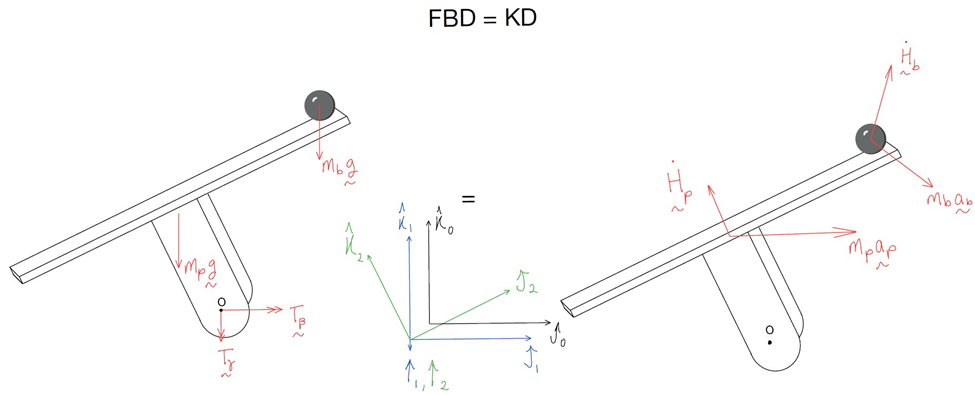

Figure 4: Free body diagram and kinetic diagram for the ball and plate combined system.$N$ and $F_f$ are internal forces here so they do not apper on the diagram. 

### Absolute Angular Momentum$H^{(1)}_P$ of the Plate about its C.O.M

This is taken about the plate's center of mass and is expressed in the S1 basis. First, the $H^{(2)}_P$ vector is found, the angular momentum of the plate in the S2 frame's basis, and then it is transformed through $R^{21}$ into the S1 frame's basis.


$$H^{(2)}_P ~=~ I_p^{(2)}*\hat{\Omega}^{(2)} $$


Where 


$$I_p^{(2)} = \left\lbrack \begin{array}{ccc}
I_p^{\textrm{xx}}  & 0 & 0\\
0 & I_p^{\textrm{yy}}  & 0\\
0 & 0 & I_p^{\textrm{zz}} 
\end{array}\right\rbrack$$


is the plate's moment of inertia tensor. Rotated into the S1 basis, $H^{(2)}_P$ becomes $H^{(1)}_P$, our desired result:

subs(Hp1s, VDefs.symFunVec, VDefs.symVarVec) %Display the angular momentum vector in an easier to read format

$$ans = \left[\begin{array}{c} I_{p}^{\mathrm{xx}}\,\dot{\gamma }\\ {\cos\left(\gamma \right)}^{2}\,I_{p}^{\mathrm{xx}}\,\dot{\beta }+{\sin\left(\gamma \right)}^{2}\,I_{p}^{\mathrm{zz}}\,\dot{\beta }\\ I_{p}^{\mathrm{xx}}\,\dot{\beta }\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)-I_{p}^{\mathrm{zz}}\,\dot{\beta }\,\cos\left(\gamma \right)\,\sin\left(\gamma \right) \end{array}\right]$$


$$H_p^{(1)} ~=~

\left\lbrack \begin{array}{c}
I_p^{\textrm{xx}} \,\gamma^˙ \\
{\mathrm{cos}\left(\gamma \right)}^2 \,I_p^{\textrm{xx}} \,\beta^˙ +{\mathrm{sin}\left(\gamma \right)}^2 \,I_p^{\textrm{zz}} \,\beta^˙ \\
I_p^{\textrm{xx}} \,\beta^˙ \,\mathrm{cos}\left(\gamma \right)\,\mathrm{sin}\left(\gamma \right)-I_p^{\textrm{zz}} \,\beta^˙ \,\mathrm{cos}\left(\gamma \right)\,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack$$


### Take the Time Derivative of the Absolute Angular Momentum, $\dot{H}^{(1)}_p$, With Respect to the Inertial Reference Frame

We must transform transform $H^{(1)}_p$ into the S0 global basis, take a time derivative, then transform back to the S1 basis. Taking the derivative with respect to an inertial reference frame ensures compliance with Newton's laws.The result of this procedure is:

Hp1ds

$$Hp1ds = \left[\begin{array}{c} \frac{\sin\left(2\,\gamma \right)\,I_{p}^{\mathrm{xx}}\,{\dot{\beta }}^{2}}{2}-\frac{\sin\left(2\,\gamma \right)\,I_{p}^{\mathrm{zz}}\,{\dot{\beta }}^{2}}{2}+I_{p}^{\mathrm{xx}}\,\ddot{\gamma }\\ {\cos\left(\gamma \right)}^{2}\,I_{p}^{\mathrm{xx}}\,\ddot{\beta }+{\sin\left(\gamma \right)}^{2}\,I_{p}^{\mathrm{zz}}\,\ddot{\beta }-\sin\left(2\,\gamma \right)\,I_{p}^{\mathrm{xx}}\,\dot{\beta }\,\dot{\gamma }+\sin\left(2\,\gamma \right)\,I_{p}^{\mathrm{zz}}\,\dot{\beta }\,\dot{\gamma }\\ \frac{I_{p}^{\mathrm{xx}}\,\ddot{\beta }\,\sin\left(2\,\gamma \right)}{2}-\frac{I_{p}^{\mathrm{zz}}\,\ddot{\beta }\,\sin\left(2\,\gamma \right)}{2}-I_{p}^{\mathrm{xx}}\,\dot{\beta }\,\dot{\gamma }+I_{p}^{\mathrm{xx}}\,\dot{\beta }\,\dot{\gamma }\,\cos\left(2\,\gamma \right)-I_{p}^{\mathrm{zz}}\,\dot{\beta }\,\dot{\gamma }\,\cos\left(2\,\gamma \right) \end{array}\right]$$


$$\dot{H}_p^{(1)}

 ~=~

\left\lbrack \begin{array}{c}
\frac{\mathrm{sin}\left(2\,\gamma \right)\,I_p^{\textrm{xx}} \,{\beta^˙ }^2 }{2}-\frac{\mathrm{sin}\left(2\,\gamma \right)\,I_p^{\textrm{zz}} \,{\beta^˙ }^2 }{2}+I_p^{\textrm{xx}} \,\gamma^¨ \\
{\mathrm{cos}\left(\gamma \right)}^2 \,I_p^{\textrm{xx}} \,\beta^¨ +{\mathrm{sin}\left(\gamma \right)}^2 \,I_p^{\textrm{zz}} \,\beta^¨ -\mathrm{sin}\left(2\,\gamma \right)\,I_p^{\textrm{xx}} \,\beta^˙ \,\gamma^˙ +\mathrm{sin}\left(2\,\gamma \right)\,I_p^{\textrm{zz}} \,\beta^˙ \,\gamma^˙ \\
\frac{I_p^{\textrm{xx}} \,\beta^¨ \,\mathrm{sin}\left(2\,\gamma \right)}{2}-\frac{I_p^{\textrm{zz}} \,\beta^¨ \,\mathrm{sin}\left(2\,\gamma \right)}{2}-I_p^{\textrm{xx}} \,\beta^˙ \,\gamma^˙ +I_p^{\textrm{xx}} \,\beta^˙ \,\gamma^˙ \,\mathrm{cos}\left(2\,\gamma \right)-I_p^{\textrm{zz}} \,\beta^˙ \,\gamma^˙ \,\mathrm{cos}\left(2\,\gamma \right)
\end{array}\right\rbrack$$


### Rotate Pertinent Vectors into the S1 Basis

The moment arm from the center of the u-joint to the plates center of mass rotates in the S1 frame: 

armp1s

$$armp1s = \left[\begin{array}{c} 0\\ -z_{p}\,\sin\left(\gamma \right)\\ z_{p}\,\cos\left(\gamma \right) \end{array}\right]$$


$$arm_p^{(1)} ~=~

\left\lbrack \begin{array}{c}
0\\
-z_p \,\mathrm{sin}\left(\gamma \right)\\
z_p \,\mathrm{cos}\left(\gamma \right)
\end{array}\right\rbrack$$


In the plate frame, this moment arm is constant, but for moments in the S1 frame, it must be rotated into the S1 basis. The moment arm to the center of mass of the ball is dynamic as well and is represented by its displacement vector in the S1 basis - we are summing moments about the origin of the coordinate systems:

rb1s

$$rb1s = \left[\begin{array}{c} x\\ y\,\cos\left(\gamma \right)-z_{b}\,\sin\left(\gamma \right)\\ z_{b}\,\cos\left(\gamma \right)+y\,\sin\left(\gamma \right) \end{array}\right]$$


$$r_b^{(1)} ~=~ 

\left\lbrack \begin{array}{c}
x\\
y\,\mathrm{cos}\left(\gamma \right)-z_b \,\mathrm{sin}\left(\gamma \right)\\
z_b \,\mathrm{cos}\left(\gamma \right)+y\,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack$$


We must also bring the ball and plate acceleration vectors, as well as $\dot{H}^{(2)}_b$, into the S1 basis.

subs(BP_Knmtcs.ap2s, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \ddot{\beta }\,z_{p}\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{\gamma }\,z_{p}\,\sin\left(\gamma \right)\\ -\frac{\sin\left(2\,\gamma \right)\,{\dot{\beta }}^{2}\,z_{p}}{2}-\ddot{\gamma }\,z_{p}\\ -{\cos\left(\gamma \right)}^{2}\,{\dot{\beta }}^{2}\,z_{p}-{\dot{\gamma }}^{2}\,z_{p} \end{array}\right]$$

subs(ap1s, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \ddot{\beta }\,z_{p}\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{\gamma }\,z_{p}\,\sin\left(\gamma \right)\\ {\dot{\gamma }}^{2}\,z_{p}\,\sin\left(\gamma \right)-\ddot{\gamma }\,z_{p}\,\cos\left(\gamma \right)\\ -\ddot{\gamma }\,z_{p}\,\sin\left(\gamma \right)-{\dot{\gamma }}^{2}\,z_{p}\,\cos\left(\gamma \right)-{\dot{\beta }}^{2}\,z_{p}\,{\cos\left(\gamma \right)}^{3}-{\dot{\beta }}^{2}\,z_{p}\,\cos\left(\gamma \right)\,{\sin\left(\gamma \right)}^{2} \end{array}\right]$$

subs(BP_Knmtcs.ab2s,VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \ddot{x}-{\dot{\beta }}^{2}\,x+\ddot{\beta }\,z_{b}\,\cos\left(\gamma \right)+\ddot{\beta }\,y\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{y}\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{\gamma }\,y\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{\gamma }\,z_{b}\,\sin\left(\gamma \right)\\ \ddot{y}-\ddot{\gamma }\,z_{b}-{\dot{\beta }}^{2}\,y-{\dot{\gamma }}^{2}\,y-\ddot{\beta }\,x\,\sin\left(\gamma \right)-2\,\dot{\beta }\,\dot{x}\,\sin\left(\gamma \right)+{\dot{\beta }}^{2}\,y\,{\cos\left(\gamma \right)}^{2}-\frac{{\dot{\beta }}^{2}\,z_{b}\,\sin\left(2\,\gamma \right)}{2}\\ \ddot{\gamma }\,y+2\,\dot{\gamma }\,\dot{y}-{\dot{\gamma }}^{2}\,z_{b}-\ddot{\beta }\,x\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{x}\,\cos\left(\gamma \right)-{\dot{\beta }}^{2}\,z_{b}\,{\cos\left(\gamma \right)}^{2}-\frac{{\dot{\beta }}^{2}\,y\,\sin\left(2\,\gamma \right)}{2} \end{array}\right]$$

subs(ab1s,VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \ddot{x}-{\dot{\beta }}^{2}\,x+\ddot{\beta }\,z_{b}\,\cos\left(\gamma \right)+\ddot{\beta }\,y\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{y}\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{\gamma }\,y\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{\gamma }\,z_{b}\,\sin\left(\gamma \right)\\ \sin\left(\gamma \right)\,\left({\dot{\gamma }}^{2}\,z_{b}-2\,\dot{\gamma }\,\dot{y}-\ddot{\gamma }\,y+\ddot{\beta }\,x\,\cos\left(\gamma \right)+2\,\dot{\beta }\,\dot{x}\,\cos\left(\gamma \right)+{\dot{\beta }}^{2}\,z_{b}\,{\cos\left(\gamma \right)}^{2}+\frac{{\dot{\beta }}^{2}\,y\,\sin\left(2\,\gamma \right)}{2}\right)-\cos\left(\gamma \right)\,\left(\ddot{\gamma }\,z_{b}-\ddot{y}+{\dot{\beta }}^{2}\,y+{\dot{\gamma }}^{2}\,y+\ddot{\beta }\,x\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{x}\,\sin\left(\gamma \right)-{\dot{\beta }}^{2}\,y\,{\cos\left(\gamma \right)}^{2}+\frac{{\dot{\beta }}^{2}\,z_{b}\,\sin\left(2\,\gamma \right)}{2}\right)\\ -\cos\left(\gamma \right)\,\left({\dot{\gamma }}^{2}\,z_{b}-2\,\dot{\gamma }\,\dot{y}-\ddot{\gamma }\,y+\ddot{\beta }\,x\,\cos\left(\gamma \right)+2\,\dot{\beta }\,\dot{x}\,\cos\left(\gamma \right)+{\dot{\beta }}^{2}\,z_{b}\,{\cos\left(\gamma \right)}^{2}+\frac{{\dot{\beta }}^{2}\,y\,\sin\left(2\,\gamma \right)}{2}\right)-\sin\left(\gamma \right)\,\left(\ddot{\gamma }\,z_{b}-\ddot{y}+{\dot{\beta }}^{2}\,y+{\dot{\gamma }}^{2}\,y+\ddot{\beta }\,x\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{x}\,\sin\left(\gamma \right)-{\dot{\beta }}^{2}\,y\,{\cos\left(\gamma \right)}^{2}+\frac{{\dot{\beta }}^{2}\,z_{b}\,\sin\left(2\,\gamma \right)}{2}\right) \end{array}\right]$$

subs(Hb1ds, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \frac{2\,\ddot{\gamma }\,m_{b}\,{r_{b}}^{2}}{5}-\frac{2\,m_{b}\,r_{b}\,\ddot{y}}{5}+\frac{2\,\dot{\beta }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{x}\,\sin\left(\gamma \right)}{5}\\ \frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}}{5}+\frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}\,{\sin\left(\gamma \right)}^{2}}{5}+\frac{2\,m_{b}\,r_{b}\,\ddot{x}\,\cos\left(\gamma \right)}{5}-\frac{2\,m_{b}\,{\dot{\psi }}_{z}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5}-\frac{2\,\dot{\gamma }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}-\frac{2\,\dot{\gamma }\,m_{b}\,r_{b}\,\dot{x}\,\sin\left(\gamma \right)}{5}\\ \frac{2\,m_{b}\,r_{b}\,\ddot{x}\,\sin\left(\gamma \right)}{5}+\frac{2\,m_{b}\,{\dot{\psi }}_{z}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{y}\,{\cos\left(\gamma \right)}^{2}}{5}-\frac{2\,\dot{\gamma }\,m_{b}\,\psi_{z}\,{r_{b}}^{2}\,\sin\left(\gamma \right)}{5}+\frac{2\,\dot{\beta }\,m_{b}\,r_{b}\,\dot{y}\,{\sin\left(\gamma \right)}^{2}}{5}-\frac{2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}}{5}-\frac{2\,\dot{\beta }\,\dot{\gamma }\,m_{b}\,{r_{b}}^{2}\,{\sin\left(\gamma \right)}^{2}}{5}+\frac{2\,\dot{\gamma }\,m_{b}\,r_{b}\,\dot{x}\,\cos\left(\gamma \right)}{5} \end{array}\right]$$

### Sum of Moments About Center of the U-Joint - Utilizing the S1 Basis 

The sum of moments within the S1 frame for the combined ball and plate system incorporates both body forces and the external torques about the u-joint axles. Since the KD terms were differentiated with respect to an inertial reference frame and then rotated into the S1 basis, this equation still represents quantities of the inertial reference frame:


$$

\begin{array}{rl}

\sum{M_{o~FBD} &=~~ \sum{M_{o~KD}\\[6pt]

arm^{(1)}_p \times R^{01}W^{(0)}_p + r^{(1)}_b\times R^{01}W^{(0)}_b + T^{(1)}_\beta+ T^{(1)}_\gamma +  M^{(1)}_z 

&=~~  arm^{(1)}_p \times m_p a^{(1)}_p + \dot{H}^{(1)}_p + r^{(1)}_b\times m_b a^{(1)}_b + \dot{H}^{(1)}_b 

\end{array}$$


This set of equations turns out to be far too large and cumbersome to display. Refer to the attached MATLAB code for detailed results. The code utilized is as follows:

SumMPlate 

## Bring Together Moment Equations and Solve for Highest Order Terms

The moment equations in the z directions of the analysis turn out to be unimportant. For the ball, the moments in the z direction simply tell us that there is no global external torque that can spin the ball, i.e. in the global frame, the ball maintains whatever angular velocity it has at the initial conditions. For the ball and plate together, the z direction moments simply tell us the magnitude of the reaction moment $M_z$ that the u-joint takes on to support the plate and ball structurally. It does not contain any pertinant dynamics. Therefore, we will bring together only the x and y direction moment equations from each of the kinetic analysis. 

The dynamics that result are functions of an important set of variables. The state vector for the system will be chosen to be


$$\tilde{x} ~=~ 

\left\lbrack \begin{array}{c}
x~
y~
\beta ~
\gamma ~
\dot{x} ~
\dot{y} ~
\beta^˙ ~
\gamma^˙ ~
\end{array}\right\rbrack^T

$$


because the system is well represented with four degrees of freedom, two rotational, and two translational. The ball can move in the plane of the plate, and the plate itself can rotate through two rotation angles. The moment equations will be solved for the derivative of this vector. The resulting nonlinear equation are too cumbersome to display, but the code that was used to solve for these highest order derivatives of the state vector is shown:

CoeffMat

$$CoeffMat = \left[\begin{array}{cccc} 0 & -m_{b}\,r_{b}\,x\,\sin\left(\gamma \right) & \frac{7\,m_{b}\,r_{b}}{5} & -m_{b}\,r_{b}\,z_{b}-\frac{2\,m_{b}\,{r_{b}}^{2}}{5}\\ -\frac{7\,m_{b}\,r_{b}}{5} & -\frac{2\,m_{b}\,{r_{b}}^{2}\,\cos\left(\gamma \right)}{5}-m_{b}\,r_{b}\,z_{b}\,\cos\left(\gamma \right)-m_{b}\,r_{b}\,y\,\sin\left(\gamma \right) & 0 & 0\\ 0 & m_{b}\,x\,y\,{\cos\left(\gamma \right)}^{3}-m_{b}\,x\,z_{b}\,{\sin\left(\gamma \right)}^{3}+m_{b}\,x\,y\,\cos\left(\gamma \right)\,{\sin\left(\gamma \right)}^{2}-m_{b}\,x\,z_{b}\,{\cos\left(\gamma \right)}^{2}\,\sin\left(\gamma \right) & \frac{2\,m_{b}\,r_{b}}{5}+m_{b}\,z_{b}\,{\cos\left(\gamma \right)}^{2}+m_{b}\,z_{b}\,{\sin\left(\gamma \right)}^{2} & -I_{p}^{\mathrm{xx}}-\frac{2\,m_{b}\,{r_{b}}^{2}}{5}-m_{b}\,y^{2}\,{\cos\left(\gamma \right)}^{2}-m_{b}\,{z_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}-m_{p}\,{z_{p}}^{2}\,{\cos\left(\gamma \right)}^{2}-m_{b}\,y^{2}\,{\sin\left(\gamma \right)}^{2}-m_{b}\,{z_{b}}^{2}\,{\sin\left(\gamma \right)}^{2}-m_{p}\,{z_{p}}^{2}\,{\sin\left(\gamma \right)}^{2}\\ -\frac{2\,m_{b}\,r_{b}\,\cos\left(\gamma \right)}{5}-m_{b}\,z_{b}\,\cos\left(\gamma \right)-m_{b}\,y\,\sin\left(\gamma \right) & -I_{p}^{\mathrm{xx}}\,{\cos\left(\gamma \right)}^{2}-I_{p}^{\mathrm{zz}}\,{\sin\left(\gamma \right)}^{2}-\frac{2\,m_{b}\,{r_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}}{5}-m_{b}\,x^{2}\,{\cos\left(\gamma \right)}^{2}-m_{b}\,{z_{b}}^{2}\,{\cos\left(\gamma \right)}^{2}-m_{p}\,{z_{p}}^{2}\,{\cos\left(\gamma \right)}^{2}-\frac{2\,m_{b}\,{r_{b}}^{2}\,{\sin\left(\gamma \right)}^{2}}{5}-m_{b}\,x^{2}\,{\sin\left(\gamma \right)}^{2}-m_{b}\,y^{2}\,{\sin\left(\gamma \right)}^{2}-2\,m_{b}\,y\,z_{b}\,\cos\left(\gamma \right)\,\sin\left(\gamma \right) & m_{b}\,x\,\sin\left(\gamma \right) & m_{b}\,x\,y\,\cos\left(\gamma \right)-m_{b}\,x\,z_{b}\,\sin\left(\gamma \right) \end{array}\right]$$

ExtTerms 

NL_EOMs;

The equations are linear in the second order derivatives and therefore the coefficients can be collected into a matrix, CoeffMat. The extra terms ExtTerms can be collected on the right hand side of the equations with the linear terms in the double dots on the left hand side. Inverting the CoeffMat matrix yields an isolated set of double dot terms. 


$$\left\lbrack \begin{array}{c}

\dot{x}\\
\ddot{x} \\
\dot\beta\\
\ddot\beta \\
\dot{y}\\
\ddot{y} \\
\dot\gamma\\
\ddot\gamma
\end{array}\right\rbrack

= 

\left\lbrack 
Nonlinear ~Equations~ of ~Motion
\right\rbrack
$$


## Best Current Estimates of Numerical System Parameters

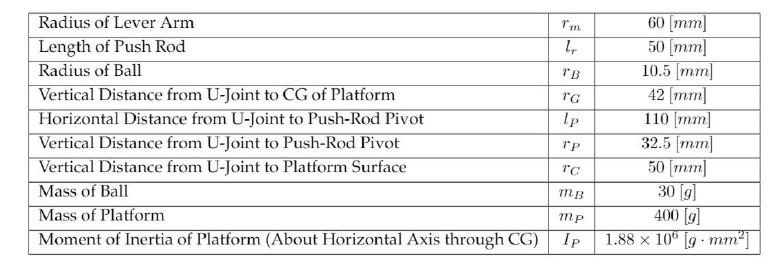

Figure 5: Estimated numerical parameters of the system, mm is converted to m and g to kg.

Num_Params

Num_Params =     0.0105    0.0605    0.0300    0.4000    0.0019    0.0000    9.8100    0.0420


Sym_Params

$$Sym\_Params = \left[\begin{array}{cccccccc} r_{b} & z_{b} & m_{b} & m_{p} & I_{p}^{\mathrm{xx}} & I_{b} & g & z_{p} \end{array}\right]$$

## Final Assumptions

We are going to assume that the angular velocity of the ball in the z direction, $\psi_z$, is insignificant and set it to zero. We will also assume that the rate of change of this angular velocity, $\dot\psi_z$, is zero. These should prove to be very accurate assumptions because the plate does not have the ability to impart a "spinning" force on the ball through its contact patch with the plates surface. The ball's spin will remain relatively close to zero so long as its initial spin is very close to zero. 

Assumption_Params

$$Assumption\_Params = \left[\begin{array}{cc} {\dot{\psi }}_{z} & \psi_{z} \end{array}\right]$$

Assumptions

Assumptions =      0     0


Substituting known numerical parameters and our assumptions into the symbolic equations of motion:

NL_NumEOMs;
